% 同一时间段，每个通道，两种刺激之间的配对样本t检验

% 数据准备
% 定义数据路径
data_path = 'D:\Matlab_data_file\EEGdata\final_eye_inspect_bad_epochs_cleared';

% 定义一个对象用于存放不同marker信息
% 'CS+：112'
% 'GS1：113'
% 'GS2：114'
% 'GS3：115'
% 'GS4：116'
% 'GS5：117'
% 'GS6：118'
% 'GS7：119'
% 'GS8：120'
% 'CS-：121'
cond = {'112','113','114','115','116','117','118','119','120','121'};

% 对于被试i：
for i = 1:4
    try
        % 拼接被试的文件名
        data_name = ['sub',num2str(i),'.set'];
        % 导入该被试数据，赋给一个叫做EEG的对象
        EEG = pop_loadset('filename',data_name,'filepath',data_path);
        % 检查EEG数据是否完好
        EEG = eeg_checkset(EEG);
        
        %对于刺激j：
        for j = 1: length(cond)
            % 从EEG对象中提取仅仅包含j刺激的epoch
            EEG_new = pop_epoch(EEG,cond(j),[-1,2],'newname','sub_cond_lv_data','epochinfo','yes');
            EEG_new = eeg_checkset(EEG_new);
            % 基线矫正
            EEG_new = pop_rmbase(EEG_new,[-1000 0]);
            EEG_new = eeg_checkset(EEG_new);
            % EEG_new.data是一个三维数据集：channel × timepoint × trial
            % 做trial水平上的均值，降维，得到二维数据集，然后添加被试变量i，条件变量j，组成四维数据集
            % EEG_avg：subject × condition × channel × timepoint
            EEG_avg(i,j,:,:) = squeeze(mean(EEG_new.data,3));
        end
    catch ME
    end
end

pop_loadset(): loading file D:\Matlab_data_file\EEGdata\final_eye_inspect_bad_epochs_cleared\sub1.set ...
eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():40 epochs selected
Epoching...
pop_epoch():40 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():15 epochs selected
Epoching...
pop_epoch():15 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():16 epochs selected
Epoching...
pop_epoch():16 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():15 epochs selected
Epoching...
pop_epoch():15 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():13 epochs selected
Epoching...
pop_epoch():13 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():15 epochs selected
Epoching...
pop_epoch():15 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():36 epochs selected
Epoching...
pop_epoch():36 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file D:\Matlab_data_file\EEGdata\final_eye_inspect_bad_epochs_cleared\sub2.set ...
eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():20 epochs selected
Epoching...
pop_epoch():20 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():14 epochs selected
Epoching...
pop_epoch():14 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():13 epochs selected
Epoching...
pop_epoch():13 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():10 epochs selected
Epoching...
pop_epoch():10 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():9 epochs selected
Epoching...
pop_epoch():9 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():18 epochs selected
Epoching...
pop_epoch():18 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file D:\Matlab_data_file\EEGdata\final_eye_inspect_bad_epochs_cleared\sub3.set ...
eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():15 epochs selected
Epoching...
pop_epoch():15 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():11 epochs selected
Epoching...
pop_epoch():11 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():9 epochs selected
Epoching...
pop_epoch():9 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():10 epochs selected
Epoching...
pop_epoch():10 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():6 epochs selected
Epoching...
pop_epoch():6 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():9 epochs selected
Epoching...
pop_epoch():9 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():15 epochs selected
Epoching...
pop_epoch():15 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file D:\Matlab_data_file\EEGdata\final_eye_inspect_bad_epochs_cleared\sub4.set ...
eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():19 epochs selected
Epoching...
pop_epoch():19 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():7 epochs selected
Epoching...
pop_epoch():7 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():8 epochs selected
Epoching...
pop_epoch():8 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():4 epochs selected
Epoching...
pop_epoch():4 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():4 epochs selected
Epoching...
pop_epoch():4 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():10 epochs selected
Epoching...
pop_epoch():10 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():9 epochs selected
Epoching...
pop_epoch():9 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():12 epochs selected
Epoching...
pop_epoch():12 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():11 epochs selected
Epoching...
pop_epoch():11 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():23 epochs selected
Epoching...
pop_epoch():23 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


pop_rmbase(): Removing baseline...


eeg_checkset: recomputing the ICA activation matrix ...


% 进行t检验
% 选择一个时间点，然后计算这个时间点前后的索引
time_oi = 150;
% 计算索引
t_idx = time_intv_index(EEG,time_oi,20);
% 按照索引提取EEG_avg中的特定数据，然后做时间维度的平均，并降维
% EEG_avg：sub*cond*chan*time ——> sub*cond*chan
data_test = squeeze(mean(EEG_avg(:,:,:,t_idx),4));

% 对于每一个通道（这里一共60个）：
for i = 1:size(data_test,3)
    % 确定两个想要比较的刺激（以1-csp，10-csm为例）
    csp_data = squeeze(data_test(:,1,i));
    csm_data = squeeze(data_test(:,10,i));
    
    % t检验
    [~,p,~,stats] = ttest(csp_data,csm_data);
    
    % 汇总每次统计的p值
    p_stats(i) = p;
    
    % 汇总t检验的参数
    t_stats(i) = stats.tstat;
end

% 清除无用的变量
clear csp_data csm_data sig p stats i j ME

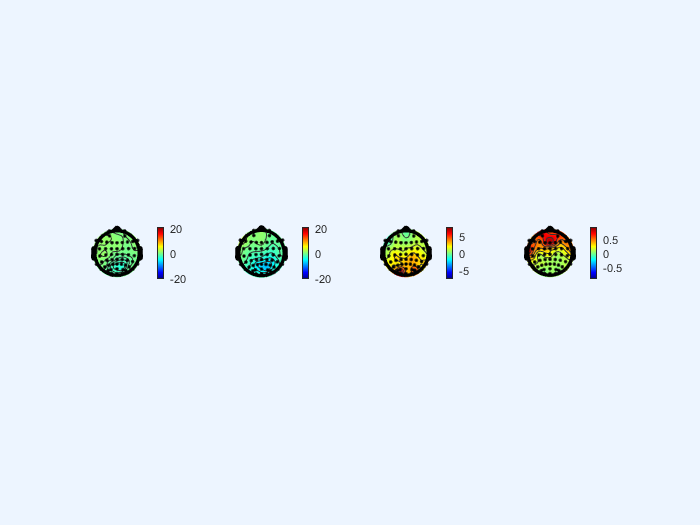

% 绘图
figure;
% csp在该时间段的全脑激活图
subplot(141);
topoplot(squeeze(mean(data_test(:,1,:),1)),EEG.chanlocs,'maplimits',[-20 20]);
colorbar;
% csm在该时间段的全脑激活图
subplot(142);
topoplot(squeeze(mean(data_test(:,10,:),1)),EEG.chanlocs,'maplimits',[-20 20]);
colorbar;
% 两个刺激对比的全脑t值图
subplot(143);
topoplot(t_stats,EEG.chanlocs);
colorbar; 
% 两个刺激对比的全脑p值图
subplot(144);
topoplot(p_stats,EEG.chanlocs);
colorbar;

function idx = time_intv_index(data,t,len)% 计算时间点索引的函数
    % data-EEG struct
    % t-time point of interest
    % len - diameter of time range to be averaged
    t_min = t - len;
    t_max = t + len;
    idx = find(data.times>t_min & data.times<t_max);
end
